## Programmierblatt 1

Jonathan Schnitzler

Matthias Gültig

Matr. - Nr: 3465192

Matr. - Nr: 3469020

Wir betrachten hier verschiedene Verfahren, um Differentialgleichungen zu lösen (Aufgabe 1) und gehen dann dazu über diese Methoden auf Leib und Seele zu testen.

*Anmerkung: Ich habe mich dazu entschieden, als klassische Funktionssyntax* `f(p,t,y)` statt `f(t,y)` *zu wählen um zusätzlich wie z.B. in Lotka Volterra benötigt Parameter einzufügen. Das macht die Funktionsdefinition etwas genereller*

### Aufgabe 1

Die Funktionen sind in einem jeweiligen script geschrieben.

### Explizites Eulerverfahren

% function Y_euler = explicit_euler(f, y_0, T, tau, param)
% if mod(T,tau)~= 0
%     warning('T should be a multiple of tau');
% end
% K = floor(T/tau);
% t = 0:tau:T; %instead tau*(k+1) works as well
% d = size(y_0,1);
% Y_euler = zeros(d,K+1);
% Y_euler(:,1) = y_0;
% 
% for k = 1:K
%     Y_euler(:,k + 1) = Y_euler(:,k) + tau * f(param, t(k),Y_euler(:,k));
% end
% 
% end

### Explizites Verfahren von Heun

% function Y_heun = explicit_heun(f, y_0, T, tau, param)
% if mod(T,tau)~= 0
%     warning('T should be a multiple of tau');
% end
% K = floor(T/tau);
% d = size(y_0,1);
% t = 0:tau:T; %instead tau*(k+1) works as well
% Y_heun = zeros(d,K+1);
% Y_heun(:,1) = y_0;
% for k = 1:K
%     f0 = f(param, t(k),Y_heun(:,k));
%     f1 = f(param, t(k + 1), Y_heun(:,k) + tau * f0);
%     Y_heun(:,k + 1) = Y_heun(:,k) + tau/2 * (f0 + f1);
% end
% 
% end

Runge Kutta Verfahren sind Einschrittverfahren die sich aus folgendem Schema zusammensetzen:


$$y_{k+1} =y_k +\tau {\;}_k \sum_{i=1}^s b_i \;f\left(t_k +c_{i\;} \tau {\;}_k ,v_i \right)$$


Wobei die $v_i$ mit folgender Gleichung definiert sind


$$v_i = y_k + \tau_k \sum_{j=1}^{s}a_{ij} f(t_k + c_j\tau_k, v_j)$$


### Runge-Kutta-Verfahren 3. Ordnung

% function yRK = explicit_runge_kutta3(f, y_0, T, tau, param)
% if mod(T,tau)~= 0
%     warning('T should be a multiple of tau');
% end
% K = floor(T/tau);
% d = size(y_0,1);
% t = 0:tau:T; %instead tau*(k+1) works as well
% yRK = zeros(d,K+1);
% yRK(:,1) = y_0;
% 
% %Was genau hier in jeder iteration passiert ist am besten mit dem
% %Butcher-Tableau zu erklären
% %     a = [0 0 0;  1/2 0 0;  -1 2 0];
% %     b = [1/6 2/3 1/6];
% %     c = [0 1/2 1];
% for k = 1:K
%     v1 = yRK(:,k);
%     v2 = yRK(:,k) + tau * 1/2 * f(param, t(k), v1);
%     v3 = yRK(:,k) + tau * (-1 * f(param,t(k),v1) + 2 * f(param,t(k)+ 1/2 * tau, v2));
%     sumV = 1/6 * f(param,t(k), v1) + 2/3 * f(param, t(k) + tau/2, v2);
%     sumV = sumV + 1/6 * f(param, t(k) + tau, v3);
%     yRK(:,k + 1) = yRK(:,k) + tau * sumV;
% end
% 
% end


### Allgemeiner Ansatz

Wie man sehen konnte sind viele Teile der Funktion gleich, weswegen man um wartbaren und einfach zu verstehenden Code zu erzeugen, etwas generalisieren sollte. Das einzige was sich im wesentlichen ändert ist die Verfahrensfunktion $\Phi(t_k, \tau_k, y_k, y_{k+1})$. Deshalb ist es sinnvoll ein Grundgerüst für jede Funktion aufzubauen und die Verfahrensfunktion, als function handle zu übergeben. 

% function y = esv(phi, f, y_0, T, tau, param)
% if mod(T,tau)~= 0
%     warning('T should be a multiple of tau');
% end
% K = floor(T/tau);
% d = size(y_0,1);
% t = 0:tau:T; %instead tau*(k+1) works as well
% y = zeros(d,K+1);
% y(:,1) = y_0;
% for k = 1:K
%     y(:,k + 1) = y(:,k) + tau * phi(t(k),tau, y(:,k), y(:,k+1), f, param);
% end
% 
% end


Eine weitere Abstraktion kann sein, dass man eine Methode für ein allgemeines RK Verfahren mit Butcher Tablaeu erstellt, aber die Aufgabe ist nicht gefordert und ich will mich nicht zu sehr verkünsteln.

### Aufgabe 2 (Räuber-Beute Modell)

%Parameter in struct p for parameter
p.alpha = 1;
p.beta = 1;
p.gamma = 1;
p.delta = 1;

%startvalue
y_0 = [0.5;0.5];

%total time
T = 20;

%step size
tau = [0.64, 0.32, 0.16, 0.08, 0.04]

tau =     0.6400    0.3200    0.1600    0.0800    0.0400



%function handle
f =  @lotkaVolterra

f = function_handle with value:
    @lotkaVolterra


Wobei die Funktion `lotkaVolterra` folgendermaßen definiert ist:

% function yDot = lotkaVolterra(p, t, y)
% yDot = zeros(2,1);
% 
% if all(y > 0) %negative input is nonsensical
%     yDot(1) = ( p.alpha -  p.beta * y(2) ) * y(1); %Change of prey
%     yDot(2) = (-p.gamma + p.delta * y(1) ) * y(2); %Change of hunter
% end
% end

Plotten wir zunächst das Phasendiagramm der Lotka-Volterra Gleichung

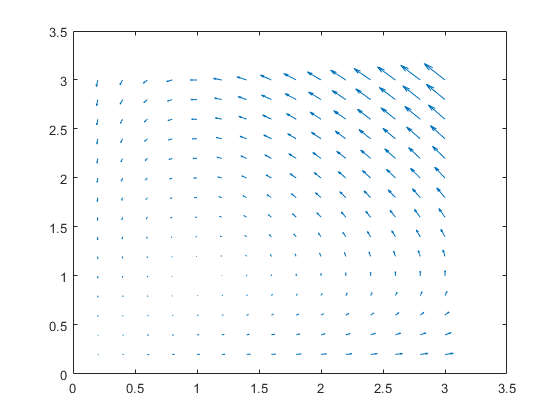

fig = figure;
nElem = 16;
meshX = linspace(0,3,nElem);
meshY = linspace(0,3,nElem);
[X,Y] = meshgrid(meshX,meshY);
U = zeros(nElem,nElem);
V = zeros(nElem,nElem);
for k = 1:nElem
    for l = 1:nElem
        foo = f(p, 0, [meshX(k),meshY(l)]);
        U(k,l) = -foo(2); %Verstehe ich nicht
        V(k,l) = -foo(1);
    end
end
quiver(X,Y,U,V);


%Refactored this code into a function since we want to use it again
figEuler = createQuiver(f, p);
hold on

Nun testen wir die in **Aufgabe 1** implementierten Verfahren

`explicit_euler:`

figPopuEul = figure;
hold on
for k = 1:numel(tau)
    Y_euler = explicit_euler(f,y_0,T,tau(k),p);
    
    %Colors and Tags
    col = k/numel(tau);
    colorHunter = [col 0 0];
    colorPrey = [0 col 0];
    nameHunter = "Hunter \tau = " + num2str(tau(k));
    namePrey = "Prey \tau =" + num2str(tau(k));
    nameBoth = "\tau = " + num2str(tau(k));
    
    
    figure(figEuler);
    plot(Y_euler(1,:),Y_euler(2,:),'DisplayName', nameBoth);
    
    figure(figPopuEul);
    t = 0:tau(k):T;
    
    plot(t,Y_euler(1,:),'Color', colorPrey,'DisplayName', namePrey);
    plot(t,Y_euler(2,:), 'Color',colorHunter, "DisplayName", nameHunter);
end

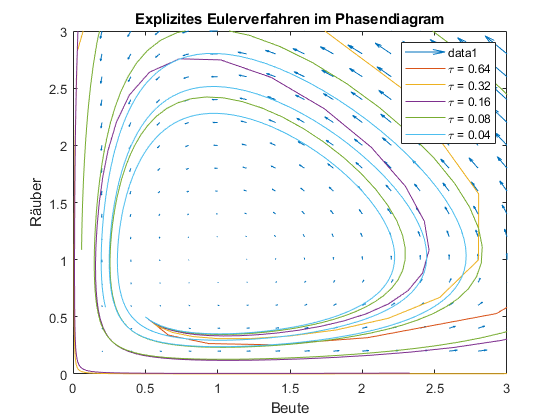


figure(figEuler)
title('Explizites Eulerverfahren im Phasendiagram')
xlabel('Beute')
ylabel('Räuber')
xlim([0 3])
ylim([0 3])
legend();

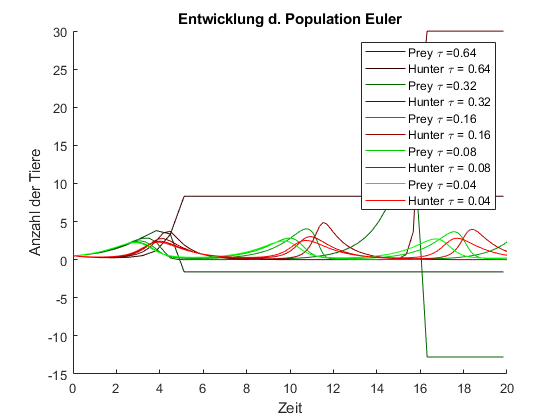


figure(figPopuEul)
title('Entwicklung d. Population Euler')
xlabel('Zeit')
ylabel('Anzahl der Tiere')
legend()

`Da man hier aber zu wenig drauf erkennen kann plotte ich jetzt und für alle kommenden Methoden jede Schrittweite `$\tau \;$einzeln.

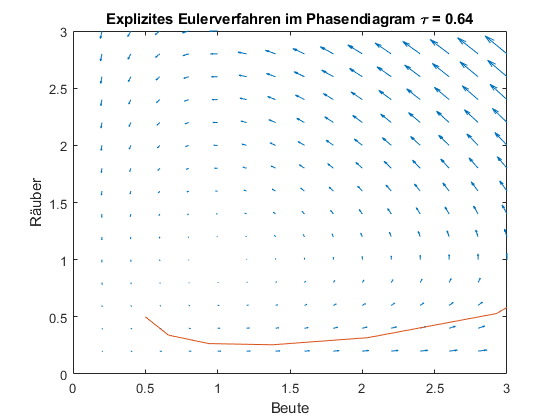

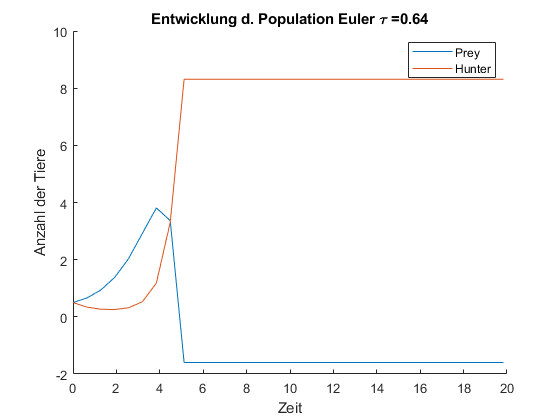

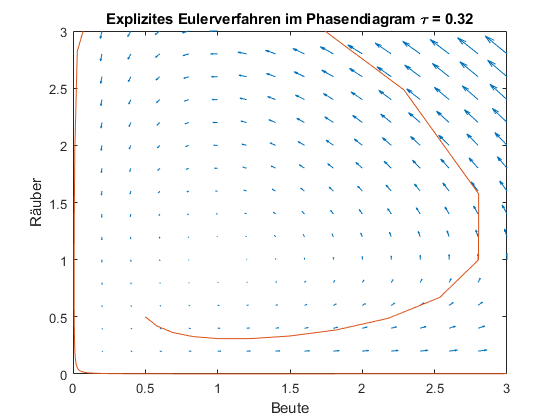

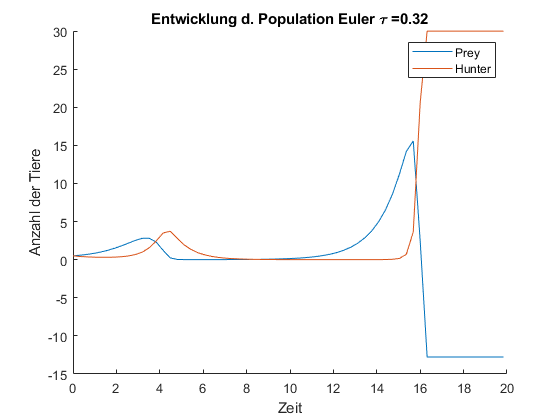

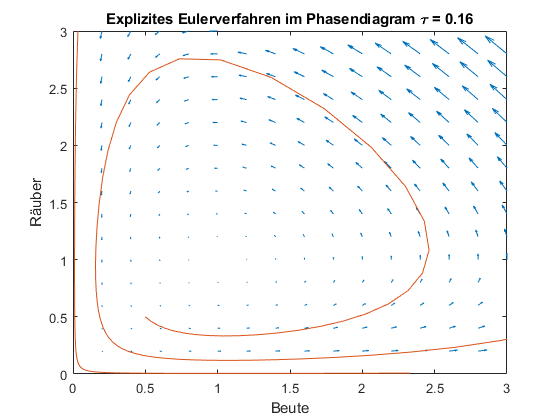

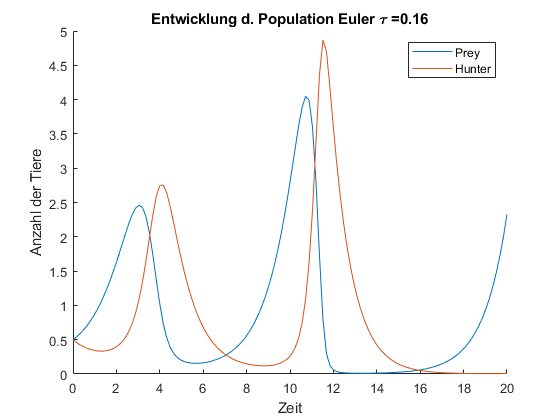

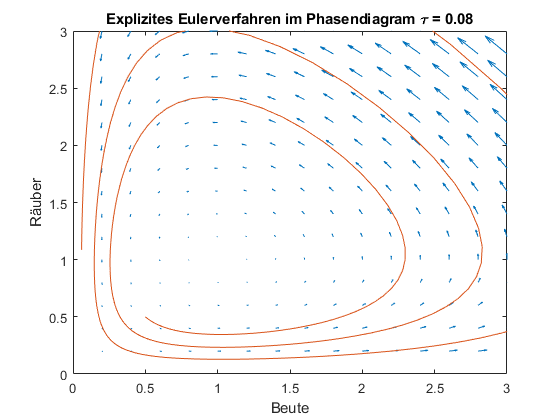

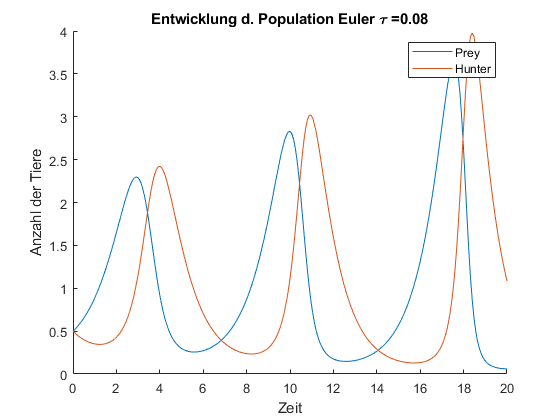

for k = 1:numel(tau)
    Y_euler = explicit_euler(f,y_0,T,tau(k),p);
    
    nameHunter = "Hunter";
    namePrey = "Prey";
    nameTau = num2str(tau(k));
    figure;
    createQuiver(f,p);
    hold on
    plot(Y_euler(1,:),Y_euler(2,:));
    title("Explizites Eulerverfahren im Phasendiagram \tau = " + nameTau)
    xlabel('Beute')
    ylabel('Räuber')
    xlim([0 3])
    ylim([0 3])
    
    
    figure;
    t = 0:tau(k):T;
    hold on
    plot(t,Y_euler(1,:),'DisplayName', namePrey);
    plot(t,Y_euler(2,:),'DisplayName', nameHunter);
    title("Entwicklung d. Population Euler \tau =" + nameTau)
    xlabel('Zeit')
    ylabel('Anzahl der Tiere')
    legend
end

`explicit_heun:`

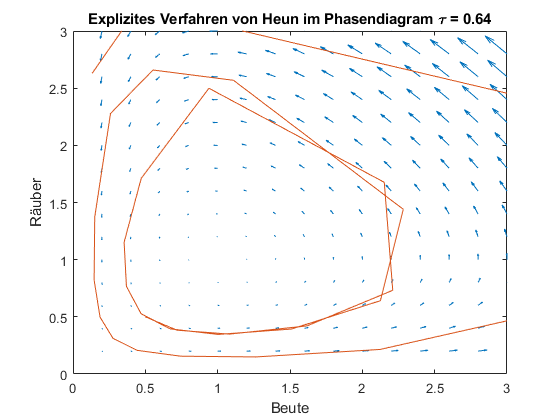

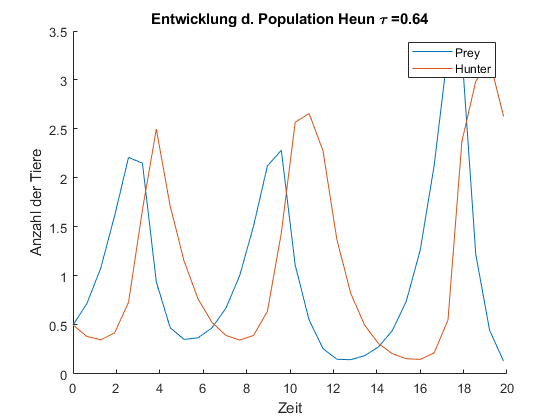

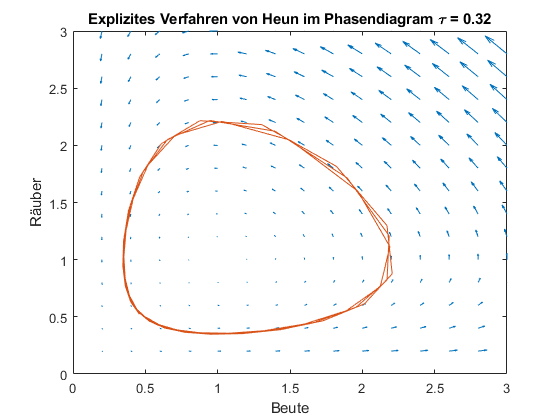

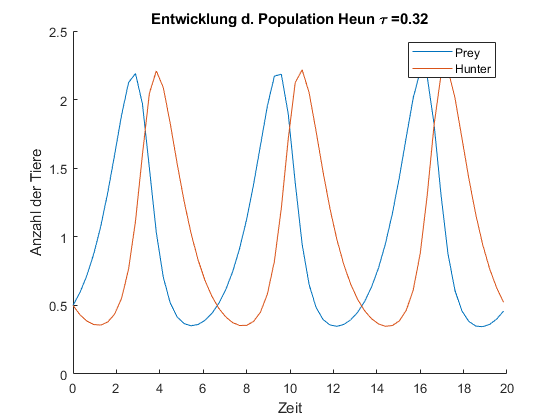

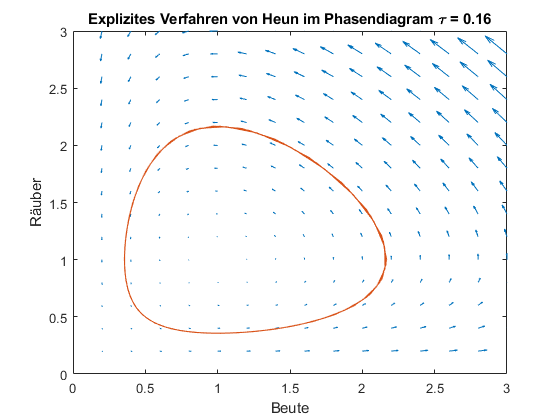

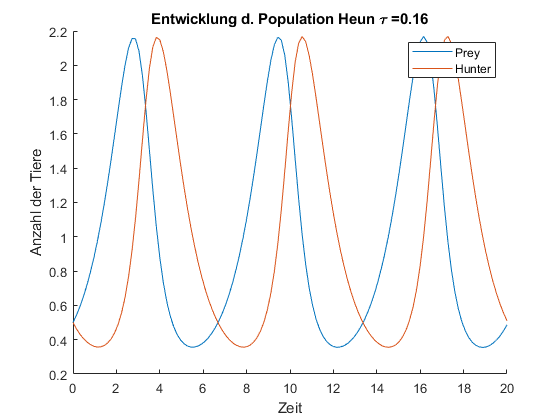

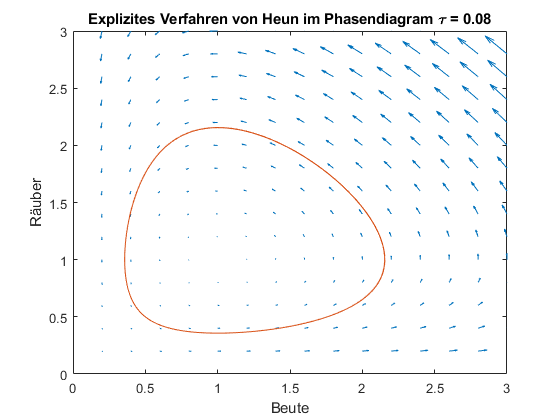

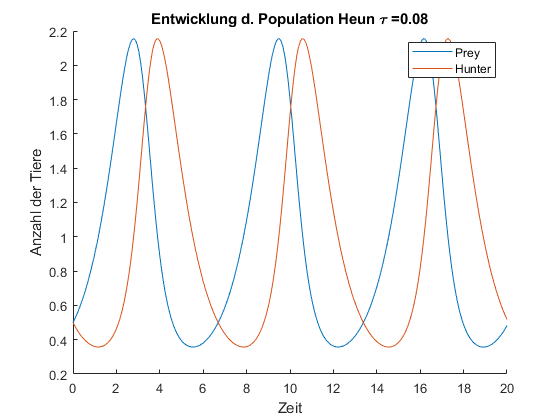

for k = 1:numel(tau)
    Y_heun = explicit_heun(f,y_0,T,tau(k),p);
    
    nameHunter = "Hunter";
    namePrey = "Prey";
    nameTau = num2str(tau(k));
    figure;
    createQuiver(f,p);
    hold on
    plot(Y_heun(1,:),Y_heun(2,:));
    title("Explizites Verfahren von Heun im Phasendiagram \tau = " + nameTau)
    xlabel('Beute')
    ylabel('Räuber')
    xlim([0 3])
    ylim([0 3])
    
    
    figure;
    t = 0:tau(k):T;
    hold on
    plot(t,Y_heun(1,:),'DisplayName', namePrey);
    plot(t,Y_heun(2,:),'DisplayName', nameHunter);
    title("Entwicklung d. Population Heun \tau =" + nameTau)
    xlabel('Zeit')
    ylabel('Anzahl der Tiere')
    legend
end

`explicit_runge_kutta3`

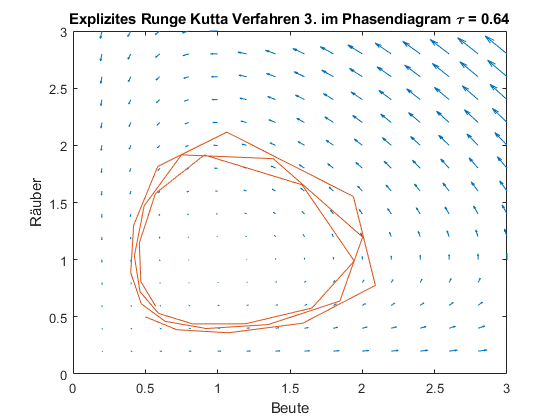

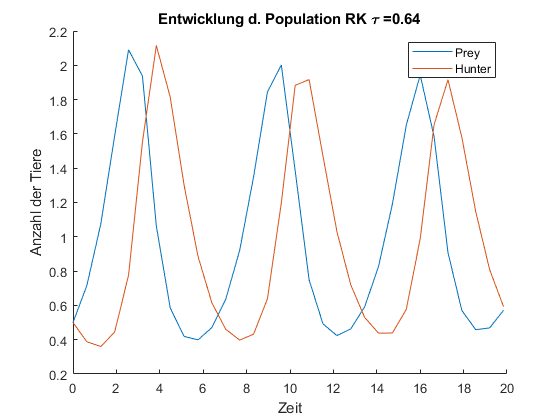

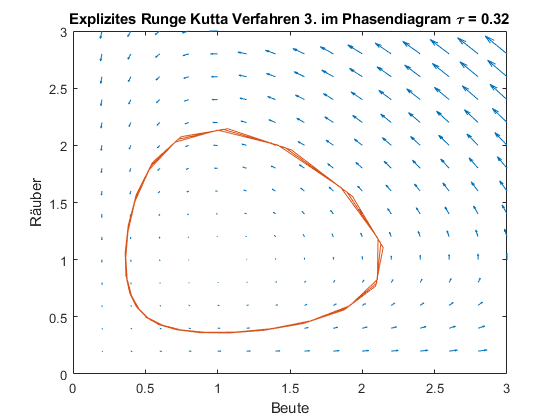

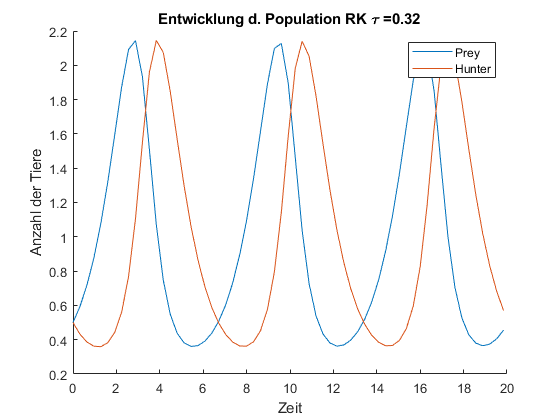

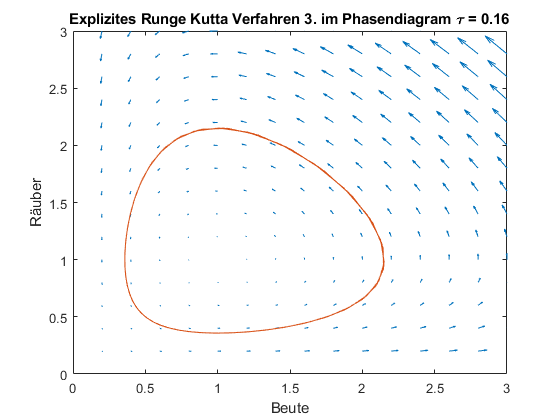

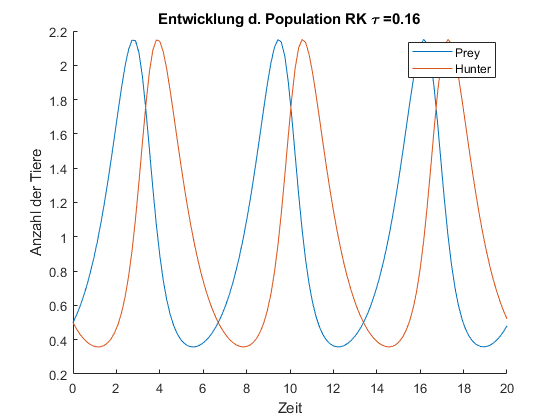

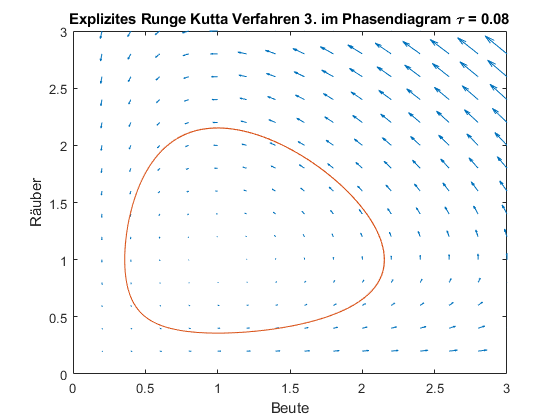

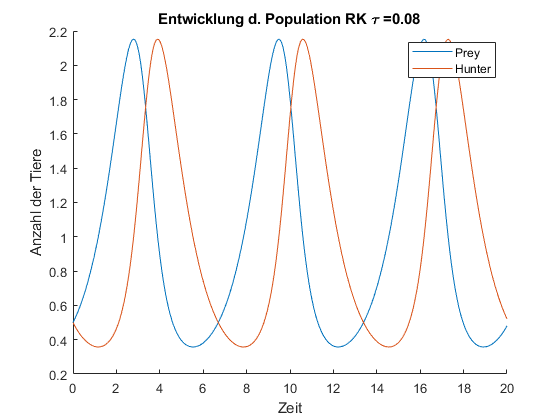

for k = 1:numel(tau)
    Y_rk3 = explicit_runge_kutta3(f,y_0,T,tau(k),p);
    
    nameHunter = "Hunter";
    namePrey = "Prey";
    nameTau = num2str(tau(k));
    figure;
    createQuiver(f,p);
    hold on
    plot(Y_rk3(1,:),Y_rk3(2,:));
    title("Explizites Runge Kutta Verfahren 3. im Phasendiagram \tau = " + nameTau)
    xlabel('Beute')
    ylabel('Räuber')
    xlim([0 3])
    ylim([0 3])
    
    
    figure;
    t = 0:tau(k):T;
    hold on
    plot(t,Y_rk3(1,:),'DisplayName', namePrey);
    plot(t,Y_rk3(2,:),'DisplayName', nameHunter);
    title("Entwicklung d. Population RK \tau =" + nameTau)
    xlabel('Zeit')
    ylabel('Anzahl der Tiere')
    legend
end

c) Fazit

Wir stellen fest, dass Euler Verfahren unterliegt dem Expliziten Verfahren von Heun und das Runge Kutta verfahren ist nochmal deutlich besser als das von Heun. Im RK für feine Schrittweiten kann man erkennen, dass die DGL tatsächlich ein geschlossener Kreis ist.

### Aufgabe 3

%parameter (pL wegen "Parameter Logistik" und weil ich das alte Struct
%nicht überschreiben wollte)
pL.alpha = 10;
pL.beta = 1/10;
pL.xi = pL.alpha/pL.beta;
pL.t_0 = 0;
pL.p_0 = 1; %MISSING VALUE 

T = 1;
tauSize = [1 9];
tau = zeros(tauSize);
for k = 0:tauSize(2)-1
    tau(k+1) = 1/80 * 2^(-k);
end

%Definition der Logistischen Funktion
logisticFun = @(pL, t, pIn) pL.alpha .* pIn - pL.beta .* (pIn.^2);

%Analytische Lösung
% function y = logisticSol(p, t)
% y = p.xi .* (p.p_0./(p.p_0 + (p.xi - p.p_0) .* exp(-p.alpha .* (t - p.t_0))));

Nun möchten wir den Fehler zu der analytischen Rechnung betrachten

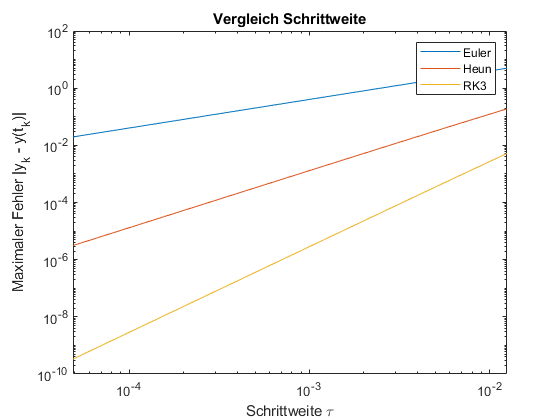

maxErrEul = zeros(tauSize);
maxErrHeun = zeros(tauSize);
maxErrRK3 = zeros(tauSize);
tCpuEul = zeros(tauSize);
tCpuHeun = zeros(tauSize);
tCpuRK3 = zeros(tauSize);

for k = 1:tauSize(2)
    figure
    t = 0:tau(k):T;
    anaSol = logisticSol(pL,t);
    
    tic
    EulSol = explicit_euler(logisticFun,pL.p_0,T,tau(k),pL);
    tCpuEul(k) = toc;
    
    tic
    HeunSol = explicit_heun(logisticFun,pL.p_0,T,tau(k),pL);
    tCpuHeun(k) = toc;
    
    tic
    RK3Sol = explicit_runge_kutta3(logisticFun, pL.p_0, T, tau(k),pL);
    tCpuRK3(k) = toc;
%     plot(t,anaSol, t,EulSol, t, HeunSol)
%     xlim([0 1])
%     ylim([0 100])
    
    
    
    errorEul = abs(anaSol-EulSol);
    errorHeun = abs(anaSol-HeunSol);
    errorRK3 = abs(anaSol - RK3Sol);
    
    
    maxErrEul(k) = max(errorEul);
    maxErrHeun(k) =max(errorHeun);
    maxErrRK3(k) = max(errorRK3);
end


loglog(tau, maxErrEul, tau, maxErrHeun, tau, maxErrRK3)
ylabel('Maximaler Fehler |y_k - y(t_k)|')
xlabel('Schrittweite \tau')
legend('Euler','Heun','RK3')
title("Vergleich Schrittweite")

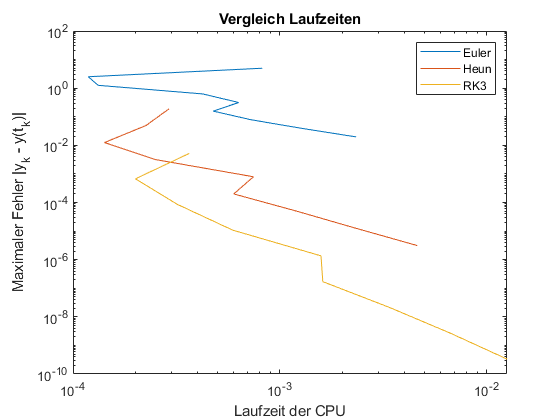


loglog(tCpuEul, maxErrEul, tCpuHeun, maxErrHeun, tCpuRK3, maxErrRK3)
ylabel('Maximaler Fehler |y_k - y(t_k)|')
xlabel('Laufzeit der CPU')
legend('Euler','Heun', 'RK3')
title("Vergleich Laufzeiten")

### Interpretation

Man erkennt, dass die Proportionalität zwischen Schrittweite und Genauigkeit bzw. maximalem Fehler tatsächlich gegeben ist. *Je kleiner die Schrittweite, desto geringer ist der Fehler*. Außerdem bestätigt sich auch hier die Vermutung, dass Euler und Heun ungenauer als Runge-Kutta 3. Ordnung ist, aber die Berechnung länger dauert. Allerdings sieht man das für die meisten Fälle auch pro Berechnungszeit* Runge Kutta das beste weil effizienteste Verfahren ist*.